% AE6705 Lab10 MATLAB code
% Tomoki Koike 
clear all; close all; clc;  % housekeeping commands
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');

% Gain and time constant from lab9
K = 1.233265815820895e+02;
tau = 0.075250836120401;

% Max overshoot less than 5% -> 4.5%
MOS = 4.5;
zeta = -log(MOS/100)/sqrt(pi^2 + log(MOS/100)^2);  % 0.702504592260657
% Rise time less than 0.5 seconds -> 0.35 seconds
tr = 0.35;
temp = 1/sqrt(1-zeta^2) * (pi - atan(sqrt(1-zeta^2)/zeta));
time_const = tr / zeta / temp;

% Tuned PID gains
% p2
% Kp = -0.00122960025714389;
% Ki = 0.0382450209614726; 
% Kd = 0.000132060829813156;
% N = 9.31086272048467;
%
% p3
Kp = 0.00572311362145534;
Ki = 0.120364997080663;
Kd = -0.000158546538651373;
N  = 36.097373491324220;

% Simulate Simulink Model
omega1 = 95;  % first candidate angular velocity 
omega2 = 120;  % second candidate angular velocity 
i = 1;

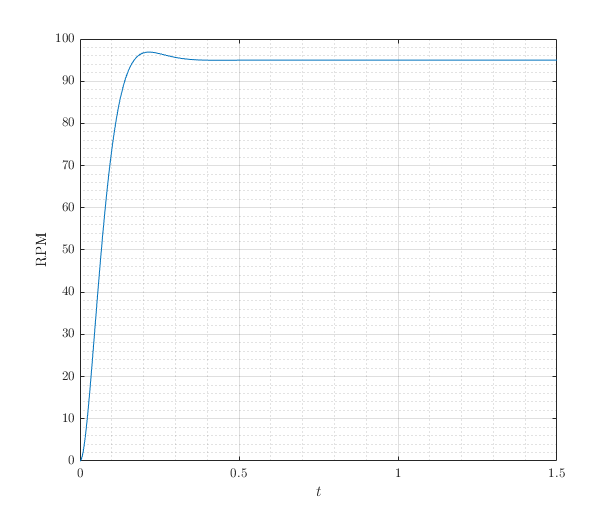

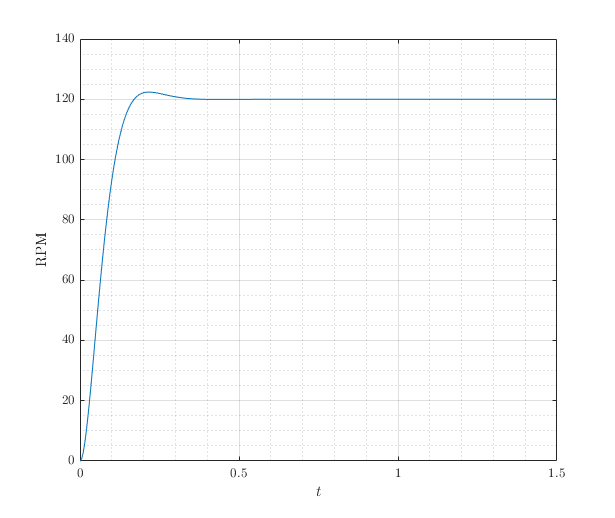

for omega = [omega1 omega2]
    res = sim("dcmotor.slx");
    % Plotting
    fig = figure("Renderer","painters","Position",[60 60 950 800]);
        plot(res.tout, res.simout.signals.values);
        grid on; grid minor; box on; 
        xlabel('$t$')
        ylabel('RPM')
    if omega == omega1
        saveas(fig,'outputs/model_response_p3_w=95.png');
    elseif omega == omega2
        saveas(fig,'outputs/model_response_p3_w=120.png');
    end
    output(i) = res;
    i = i + 1;
end

% Response characteristics - transient and steady state
rc = stepinfo(res.simout.signals.values,res.tout)

rc = struct with fields:
         RiseTime: 0.1034
    TransientTime: 0.1558
     SettlingTime: 0.1558
      SettlingMin: 108.2727
      SettlingMax: 122.3900
        Overshoot: 1.9917
       Undershoot: 0
             Peak: 122.3900
         PeakTime: 0.2129


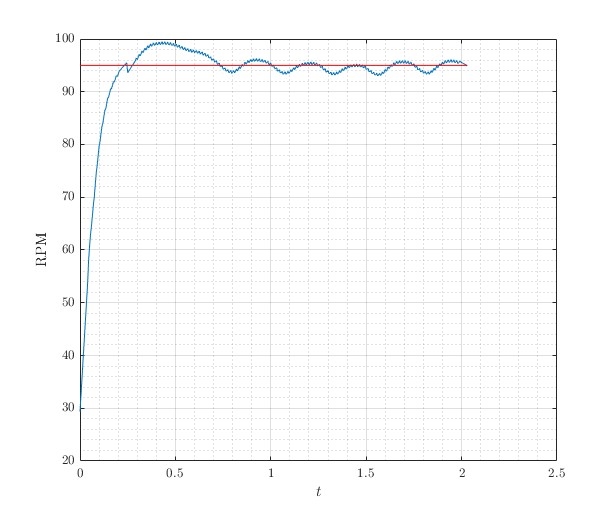

% omega = 95 
% read data
data1 = csvread("p3_omega=95.csv");
data11 = data1(1:50);
data12 = data1(51:end);
% Filter the data a bit removing outliers
data11 = sgolayfilt(data11,1,17);
data12 = rmoutliers(data12);
data12 = sgolayfilt(data12,1,17);
data1 = [data11; data12];

tspan1 = 0:0.005:0.005*(length(data1)-1);
% Plotting
fig = figure("Renderer","painters","Position",[60 60 950 800]);
    plot(tspan1, data1);
    grid on; grid minor; box on; hold on;
    plot(tspan1, 95 * ones(1, length(data1)), 'r')
    hold off;
    xlabel('$t$')
    ylabel('RPM')
saveas(fig,'outputs/actual_response_p3_w=95.png');

% Response analysis
rc95 = stepinfo(data1, tspan1)

rc95 = struct with fields:
         RiseTime: 0.1256
    TransientTime: 1.8351
     SettlingTime: 1.5603
      SettlingMin: 86.4440
      SettlingMax: 99.4873
        Overshoot: 4.8281
       Undershoot: 0
             Peak: 99.4873
         PeakTime: 0.4300


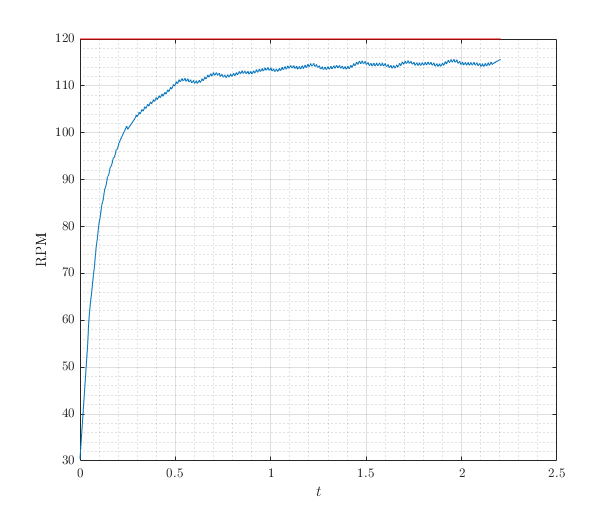

% omega = 120
% read data
data2 = csvread("p3_omega=120.csv");
data21 = data2(1:50);
data22 = data2(51:end);
% Filter the data a bit removing outliers 
data21 = sgolayfilt(data21,1,17);
data22 = rmoutliers(data22);
data22 = sgolayfilt(data22,1,17); 
data2 = [data21; data22];

tspan2 = 0:0.005:0.005*(length(data2)-1);
% Plotting
fig = figure("Renderer","painters","Position",[60 60 950 800]);
    plot(tspan2, data2);
    grid on; grid minor; box on; hold on;
    plot(tspan2, 120 * ones(1, length(data2)), 'r')
    hold off;
    xlabel('$t$')
    ylabel('RPM')
saveas(fig,'outputs/actual_response_p3_w=120.png');

% Response analysis
rc120 = stepinfo(data2, tspan2)

rc120 = struct with fields:
         RiseTime: 0.3072
    TransientTime: 1.6532
     SettlingTime: 1.0519
      SettlingMin: 104.0249
      SettlingMax: 115.6861
        Overshoot: 0.0299
       Undershoot: 0
             Peak: 115.6861
         PeakTime: 1.9600


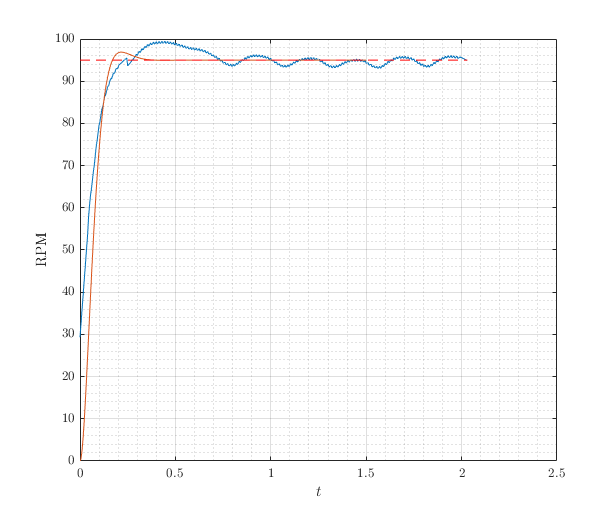

% Overlaid plots
res = output(1);
fig = figure("Renderer","painters","Position",[60 60 950 800]);
    plot(tspan1, data1);
    grid on; grid minor; box on; hold on;
    plot(res.tout, res.simout.signals.values)
    plot(tspan1, 95 * ones(1, length(data1)), '--r')
    hold off;
    xlabel('$t$')
    ylabel('RPM')
saveas(fig,'outputs/actual_response_overlaid_p3_w=95.png');

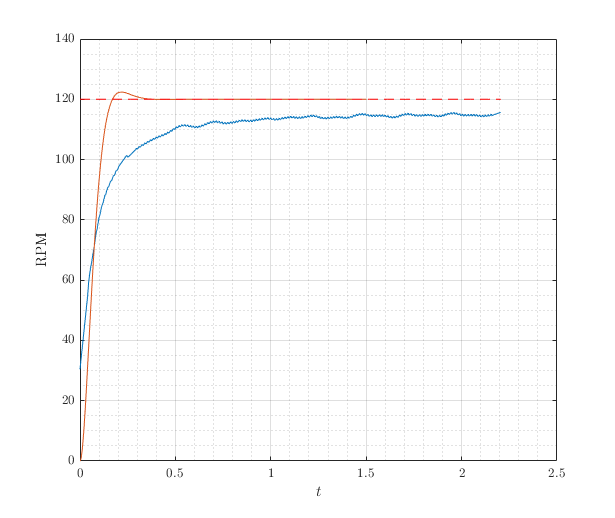

res = output(2);
fig = figure("Renderer","painters","Position",[60 60 950 800]);
    plot(tspan2, data2);
    grid on; grid minor; box on; hold on;
    plot(res.tout, res.simout.signals.values)
    plot(tspan2, 120 * ones(1, length(data2)), '--r')
    hold off;
    xlabel('$t$')
    ylabel('RPM')
saveas(fig,'outputs/actual_response_overlaid_p3_w=120.png');

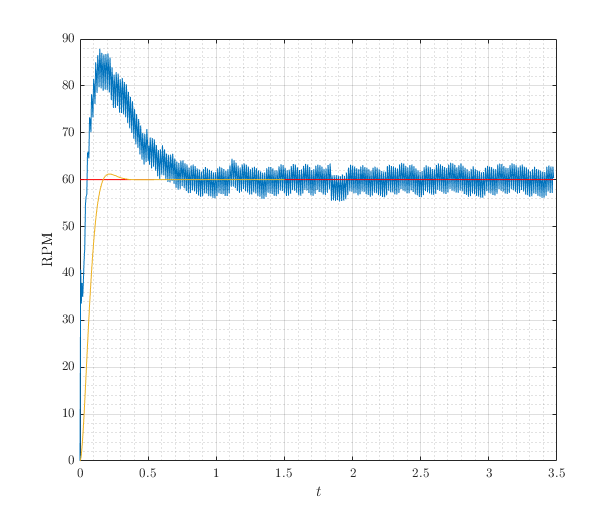

% P4: omega = 60
% read data
data4 = csvread("p4_omega=60.csv");
data41 = data4(1:100);
data42 = data4(101:end);
% Filter the data a bit removing outliers 
% data41 = sgolayfilt(data41,1,17);
data42 = rmoutliers(data42);
% data42 = sgolayfilt(data42,1,17); 
data4 = [data41; data42];

tspan4 = 0:0.005:0.005*(length(data4)-1);
% Plotting
omega = 60;
res = sim("dcmotor.slx");

fig = figure("Renderer","painters","Position",[60 60 950 800]);
    plot(tspan4, data4);
    grid on; grid minor; box on; hold on;
    plot(tspan4, 60 * ones(1, length(data4)), 'r')
    plot(res.tout, res.simout.signals.values);
    hold off;
    xlabel('$t$')
    ylabel('RPM')
saveas(fig,'outputs/actual_response_p4_w=60.png');

% Response analysis
rc60 = stepinfo(data4, tspan4)

rc60 = struct with fields:
         RiseTime: 0.0391
    TransientTime: 3.4725
     SettlingTime: 3.4725
      SettlingMin: 54.6334
      SettlingMax: 87.8898
        Overshoot: 45.6143
       Undershoot: 0
             Peak: 87.8898
         PeakTime: 0.1450
